# **Multi-hazard Analysis Scenario Analysis (MhAST) Toolbox**

**Author: Mohammad Bizhanimanzar**

**Source: **

## Section 1: MhAST modules (Flowchart)

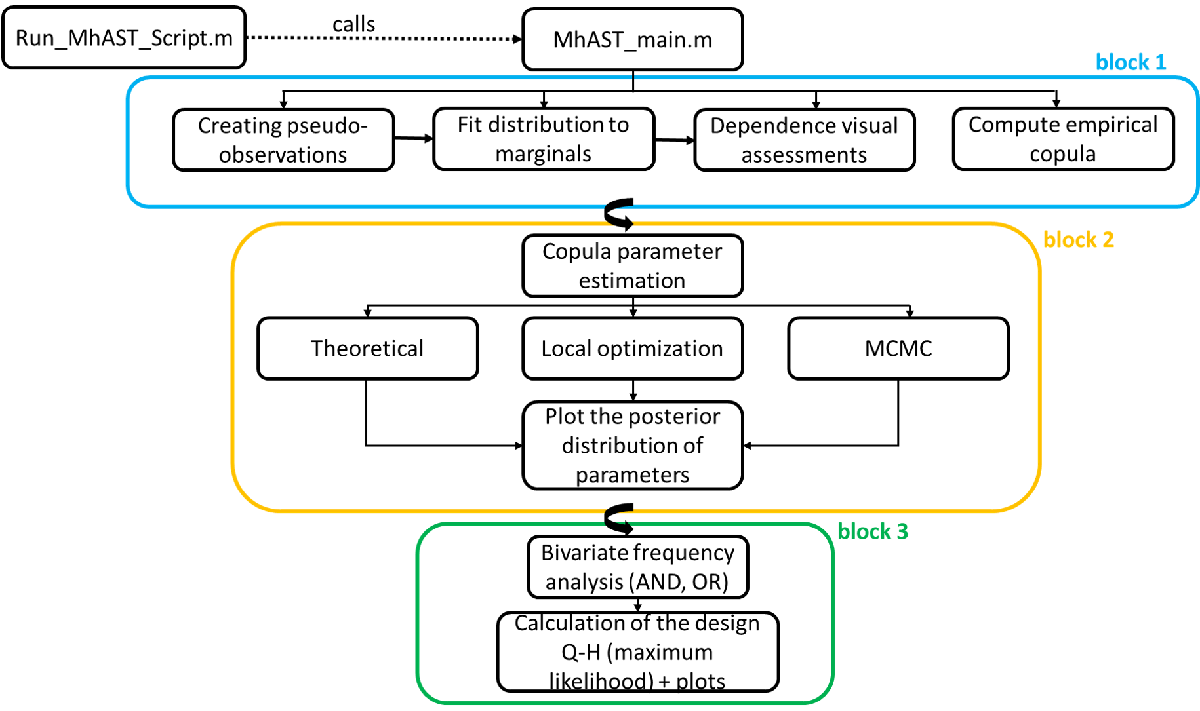

## **Working example**

**Analysis of compound flooding of Saint_Maurice river outlet (serie WLcondQ). Lets take a look at the Run_MhAST_Script.m**

%% User Input
% Data file name
datafile = 'WLcondQ.csv';
handles.title = 'WLcondQ';
% handles.title = 'QcondWL';

% Sampling frequency (how many samples per year?)
handles.SF = 1;
% Design Return Period
handles.DesignRP = 100;
% Number of weighted samples on the design return period curve
handles.WeightedSampleSize = 2000;
% Uncertainty requested?
handles.DesignUnc = 0;
% Name of the variables
handles.U1_name = 'Discharge (m^3/s)';
handles.U2_name = 'Water level (m)';

% Local optimization or Global
handles.Optimization = 'MCMC'; % Local: local optimization; MCMC: both local & global optimization

% Which Copulas to run? Select any combination
% 1: Gaussian, 2: t, 3: Clayton, 4: Frank, 5: Gumbel, 6: Independence, 7: Ali-Mikhail-Haq (AMH), 8: Joe
% 9: Farlie-Gumbel-Morgenstern (FGM), 10: Gumbel-Barnet, 11: Plackett, 12: Cuadras-Auge, 13: Raftery
% 14: Shih-Louis, 15: Linear-Spearman, 16: Cubic, 17: Burr, 18: Nelson, 19: Galambos, 20: Marshal-Olkin
% 21: Fischer-Hinzmann, 22: Roch-Alegre, 23: Fischer-Kock, 24: BB1, 25: BB5, 26: Tawn
handles.ID_CHOSEN = [1:25];

% Calculate pvalues or not? 0: no pvalue; 1: pvalue for the best copula
% selected according to BIC; 2: pvalue for all chosen copulas
handles.pvalue = 2;

handles.Kendall=0;
handles.empiricalcopula = 0; % 1 = add the empirical copula plot to the return periods or 0 (not)

% Load data
if ismac
    addpath([pwd,'/Data'])
elseif ispc
    addpath([pwd,'\Data'])
elseif isunix
    addpath([pwd,'/Data'])
end

try
    handles.data = csvread(datafile,1,4);
catch
    handles.data = load(datafile);
end

**Now call the MhAST_main.m script. Before running the main function, put a breakpoint at line 571 to investigate the quality of marginal fits and perform the visual assessment of the dependence using K-plot, Chi-plot, and scatterplot of the pseudo-observations. As it was explained in LOT3 report, this step is very important for identifying potential copulas that may represent the observed dependence in the joint dataset.**

% Run main MhAST function
[ID_ML,ID_AIC,ID_BIC,Family] = MhAST_main(handles);

Now let investigate the quality of maginal fits:

openfig('Results\Marginal\Variable 1 marginal distribution.fig','visible')
openfig('Results\Marginal\Variable 2 marginal distribution.fig','visible')

the parameters of the marginal distributions as well as the 95% uncertainty range is given in two struct variables D_U1 (for variable 1) and D_U2 (for variable 2). Lets open them:

openvar('D_U1')
openvar('D_U2')

**IMPORTANT:**** for some distributions, the parameter or the uncertainty can be infinite (-Inf). This can be a sign that the distribution is not a good fit (even if it is selected as the best based on BIC, AIC metric). Therefore, always check the selected marginal distributions for the quality of fit and validity of the parameter range. you can remove this problematic distribution from the list of tested distributions in Data/allfitdist.m file.**

**Now lets have a look at the visual assessment plots (Kendall, Chi, and scatterplot of pseudo-observations). see **[**Genest et al., 2007**](https://ascelibrary.org/doi/10.1061/%28ASCE%291084-0699%282007%2912%3A4%28347%29) and **rapport LOT3, livrable 1 for more details.**

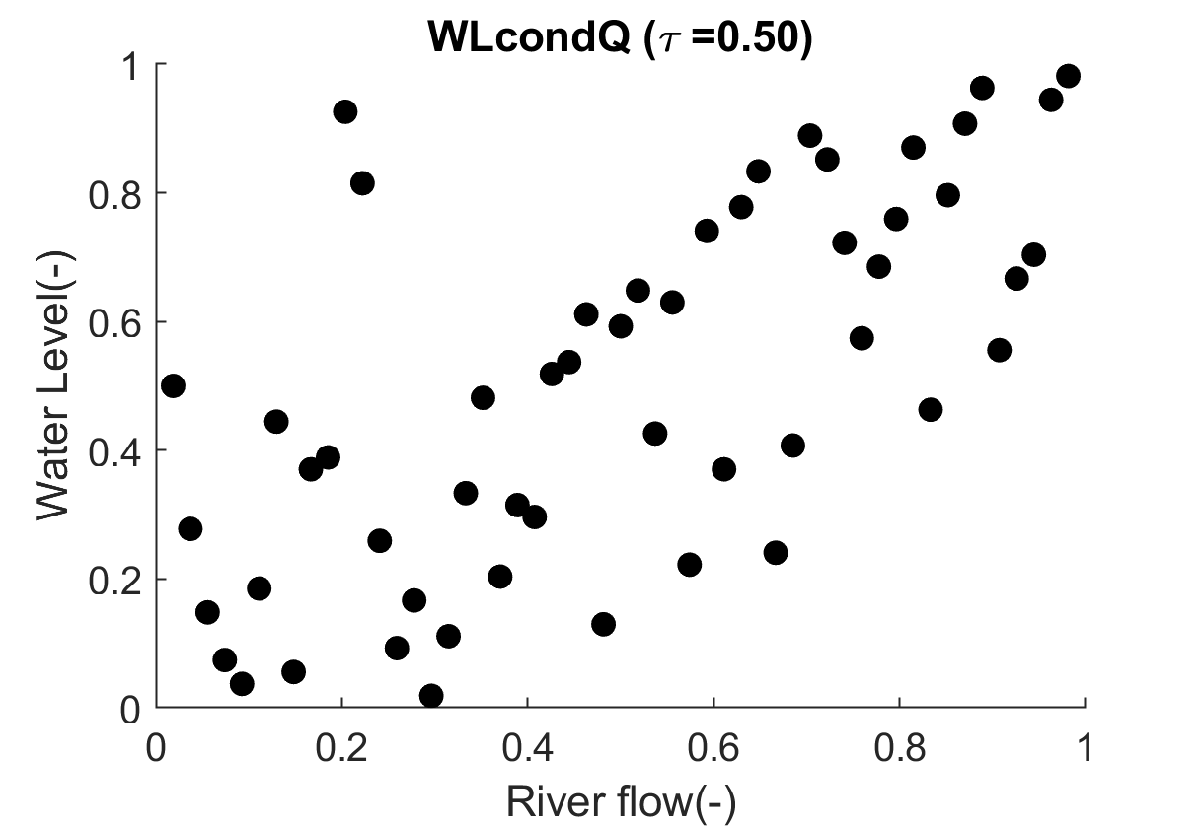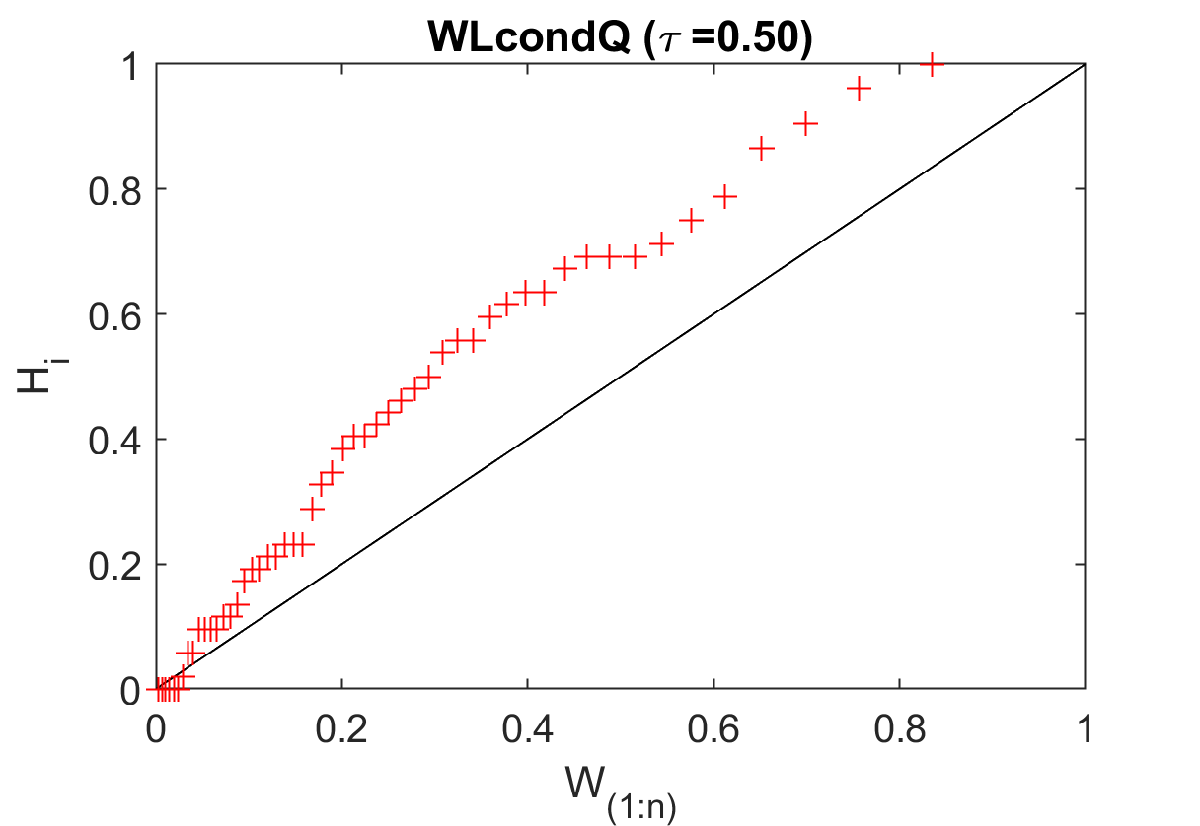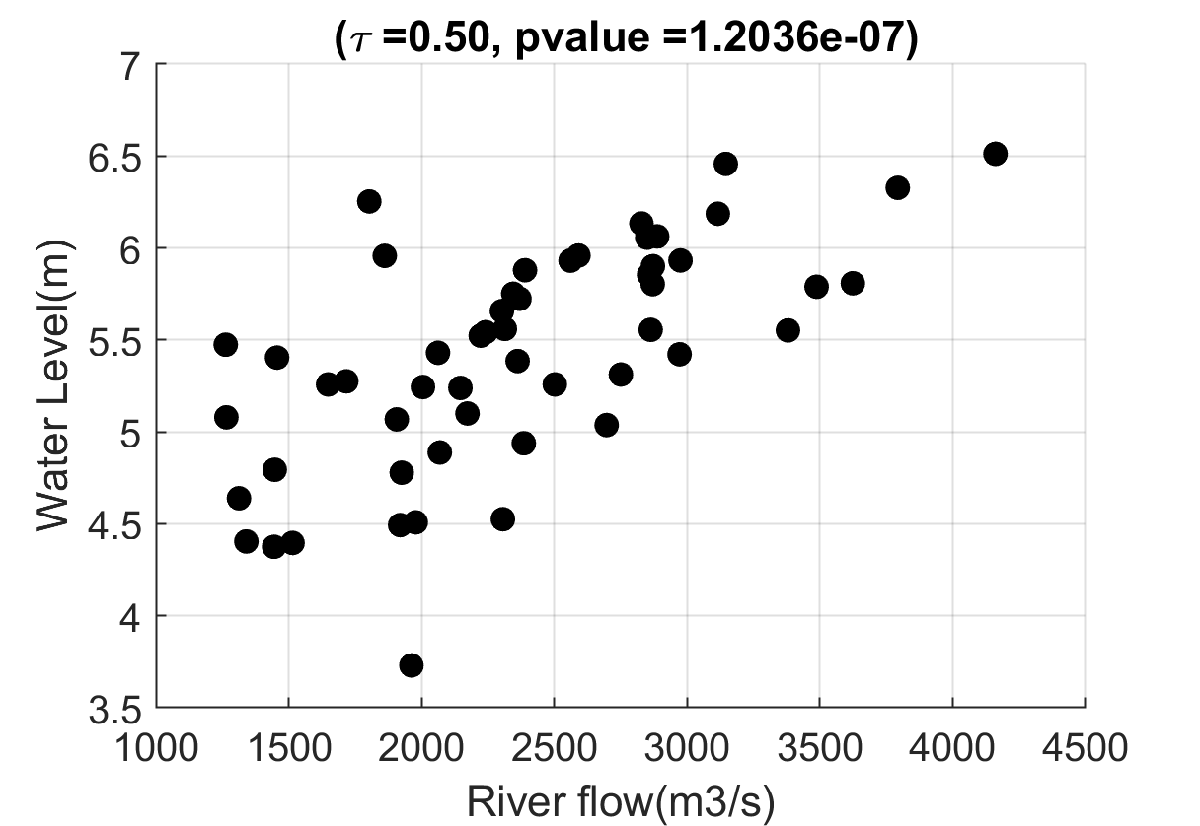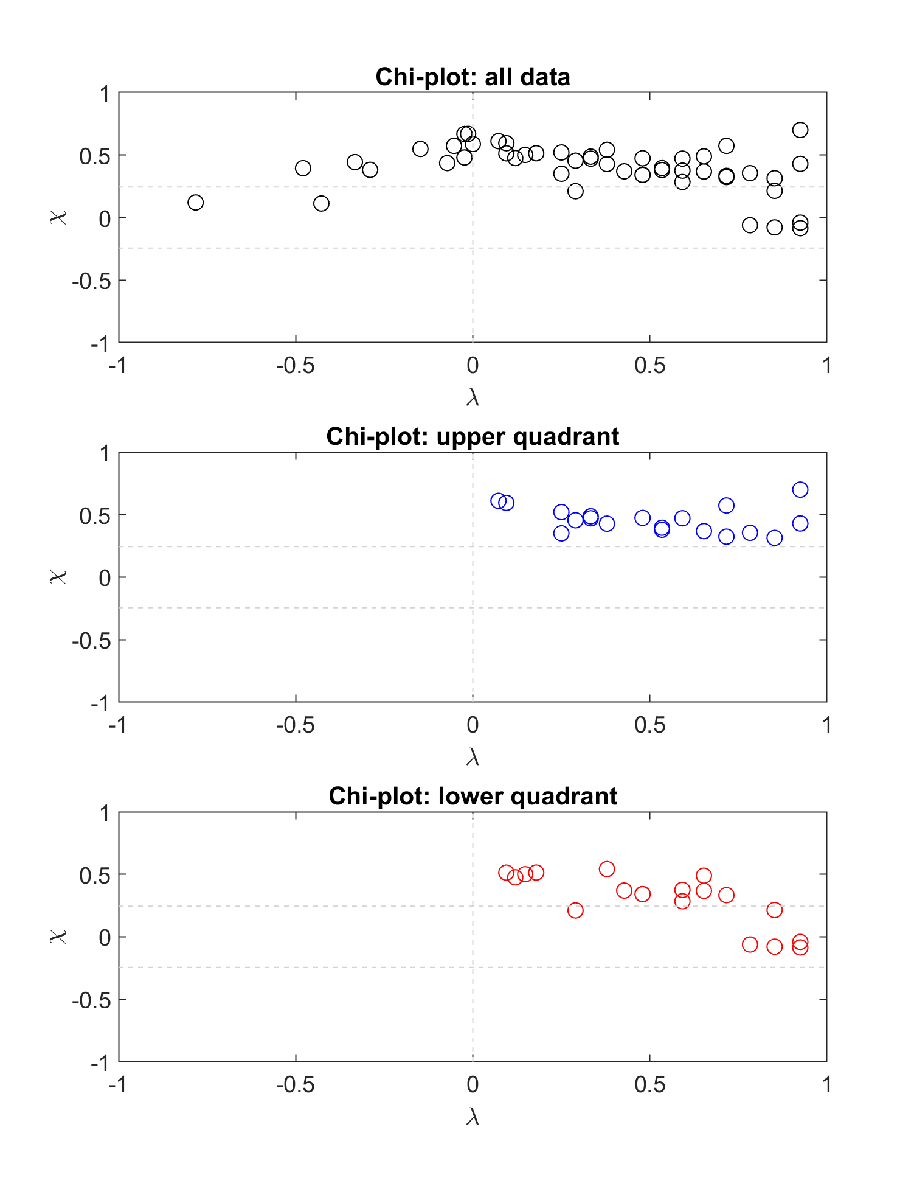

**The visual methods, already give you a good sense of the type of dependence that can be detected in the joint dataset. In case there is not statistically significant dependence between the joint variables, you can run the module only for independent copula (selected 6 in the handles.ID_CHOSEN command in Run_MhAST_Script). In this case, we are looking for an extreme type copula because of strong upper-tail dependency in the dataset. Note that the there is no statistically significant lower-tail dependency is observed in the data. To quantitatively measure the upper-tail dependency of the observed data, the Capéraà-Fougèrese-Genest estimator (\lambda CFG) is implemented in the code. Ideally, the upper-tail dependency of the fitted copula is close to the (\lambda CFG).**

## **Parameter estimation**

**To investigate the parameter estimation module, lets put a breakpoint at line 720 (after the parameter estimation block), and rerun the code.**

openfig('Results\copula\ParameterHist\Parameter Histogram-1.fig','visible')
openfig('Results\copula\ParameterHist\Parameter Histogram-2.fig','visible')
openfig('Results\copula\ParameterHist\Parameter Histogram-3.fig','visible')
openfig('Results\copula\ParameterHist\Parameter Histogram-4.fig','visible')
openfig('Results\copula\ParameterHist\Parameter Histogram-5.fig','visible')


**For the purpose of saving time, we run the MhAST only for Clayton, Frank, Gumbel, Independence, and Galambos. for this, change the ID_CHOSEN line in Run_MhAST_Script to:**

handles.ID_CHOSEN = [3,4,5,6,18];

**and then rerun the Run_MhAST_Script.m script. It takes about 5 minutes... Any question so far?**

**The SummaryReport.txt file opens upon successful execution of the code. Looking at these results show that Clayton and Independent copula re not admissible, because their p-value is smaller than 0.05. **

**IMPORTANT 1:**** this p-value corresponds to Cramér-Von-Mises (Sn) metric based on parametric bootstrap (N=250) to accept/reject the null hypothesis: The empirical copula (represented by the observations) is a memeber of the parametrirc copula. So in case the p-value is smaller than 0.05 (which is the case of independent and Clayton copula), such hypothesis can be rejected with 95% confidence level.**

**IMPORTANT 2: ****It can be seen that the Frank copula has the minimum Sn. But, we know that this copula has no upper/lower tail dependency. This highlights that only relying on numerical goodness of fit metrics for selection of the best copula is not a reliable strategy. The selection of best copula should always be based on numerical and visual goodness of fit assessments.**

## **Bivariate frequency analysis (AND scenario)**